# exploratory

data=exp6.'

data =     0.5000         0
    0.7500         0
    1.0000         0
    1.2500         0
    1.5000         0
    1.7500         0
    1.7500    1.0000
    2.0000         0
    2.2500    1.0000
    2.5000         0


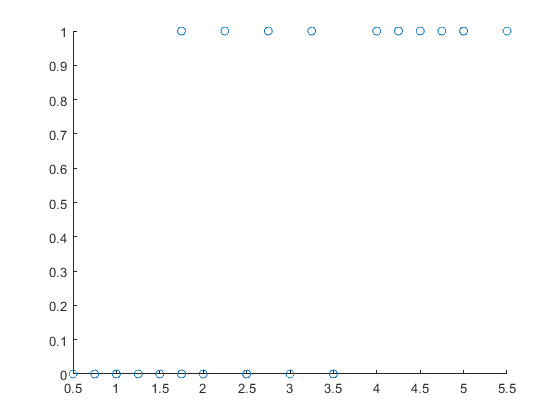

scatter(data(:,1),data(:,2))
hold on

## fit

B=mnrfit(data(:,1),data(:,2)+1)

B =     4.0777
   -1.5046


f=@(B,x) 1./(1+exp((B(1)+B(2)*x)))

f = 包含以下值的 function_handle :
    @(B,x)1./(1+exp((B(1)+B(2)*x)))


X=linspace(0,6,100)

X =          0    0.0606    0.1212    0.1818    0.2424    0.3030    0.3636    0.4242    0.4848    0.5455    0.6061    0.6667    0.7273    0.7879    0.8485    0.9091    0.9697    1.0303    1.0909    1.1515    1.2121    1.2727    1.3333    1.3939    1.4545    1.5152    1.5758    1.6364    1.6970    1.7576    1.8182    1.8788    1.9394    2.0000    2.0606    2.1212    2.1818    2.2424    2.3030    2.3636    2.4242    2.4848    2.5455    2.6061    2.6667    2.7273    2.7879    2.8485    2.9091    2.9697


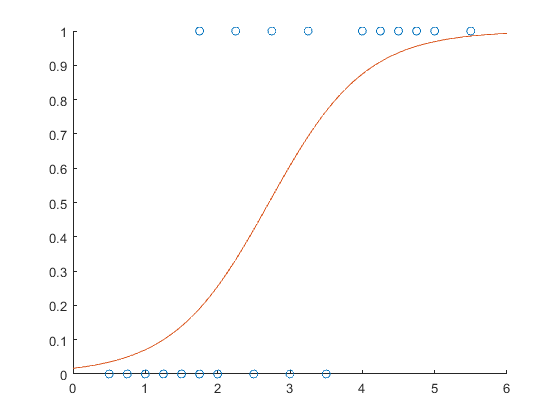

plot(X,f(B,X))